# 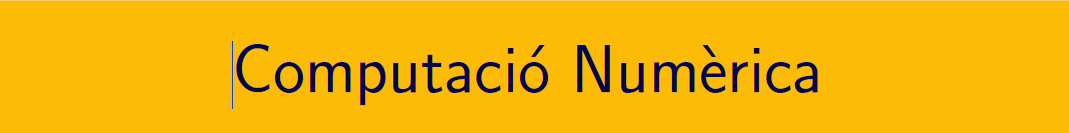

`===================================================================================`

# Pràctica 14. Equacions diferencials ordinàries (IV).

`Document preparat per M. Àngela Grau Gotés - 29 de maig de 2023`

## `Sistemes d'equacions diferencials de primer ordre`

### `Exemple: Equacions de Lorentz `

`Documentació `[`Atractor de Lorenz`](https://en.wikipedia.org/wiki/Lorenz_system)

$	PVI ::\left\lbrace \begin{array}{rcl}
			x^{\prime}(t)&=&ax+yz\,, \\ 
                        y^{\prime}(t)&=&b(y-z)\,, \\
                        z^{\prime}(t)&=&-xy+cy-z\,, \\
\end{array}\right.\quad
x(0) =y(0) =z(0)=1\,,
$º

`Per als valors `$a = -\frac83\,\ b=-10\,,\ c=28\,.$

### `Solucions aproximades numèricament O(h^4)`

- `Mètode ode45`

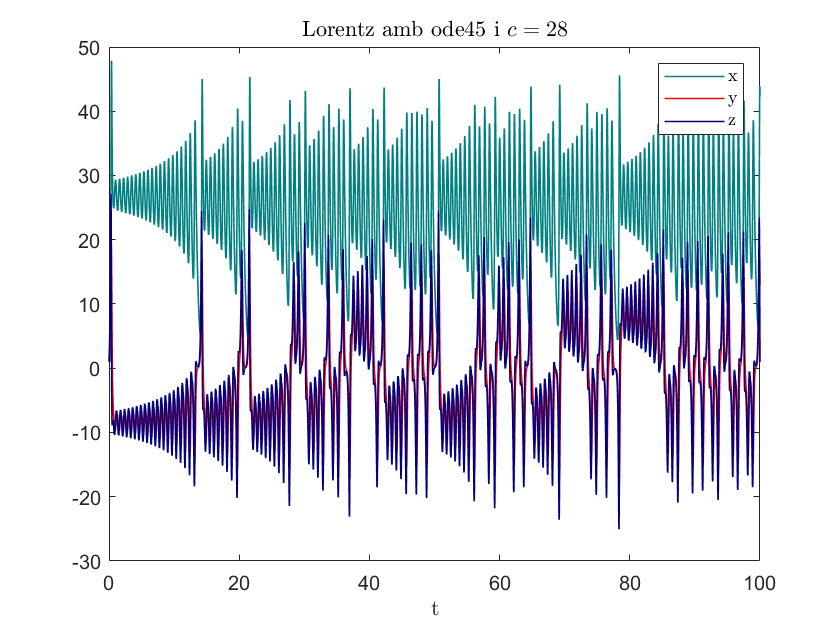

close all, clear all,
[t,y] = ode45(@edos1,[0 100],[1; 1; 1]);
 
figure(1)
plot(t, y(:,1),'Color',[0 0.5 0.5], 'LineWidth',0.8)
hold on
plot(t, y(:,2),'Color',[1 0 0], 'LineWidth',0.8)
plot(t, y(:,3),'Color',[0 0 0.5], 'LineWidth',0.8)
legend('x','y','z','Interpreter', 'latex')
title('Lorentz amb ode45 i $c = 28$','Interpreter', 'latex')
xlabel('t', 'Interpreter',"latex")
hold off

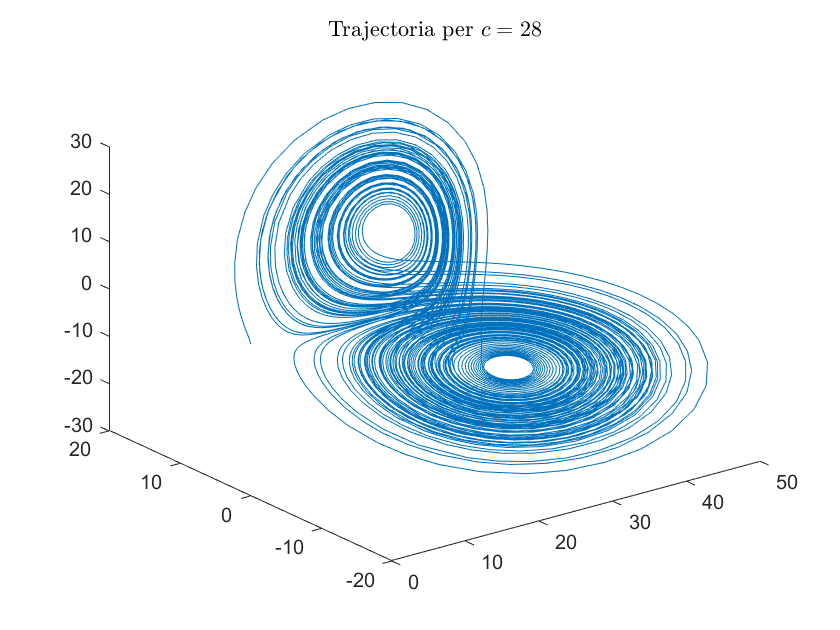


figure(2)
plot3(y(:,1),y(:,2),y(:,3))
title('Trajectoria per $c = 28$','Interpreter', 'latex')

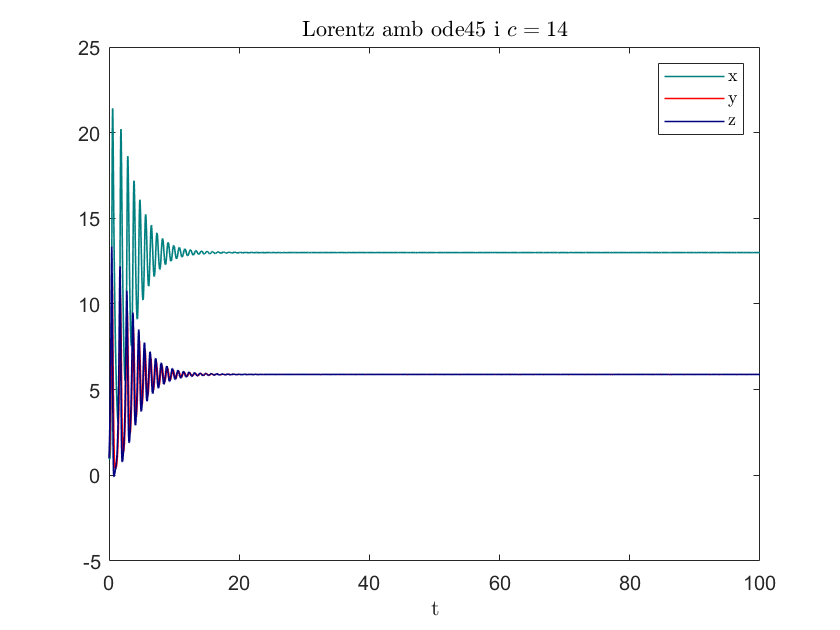


% edos2
[t,y] = ode45(@edos2,[0 100],[1; 1; 1]);
 
figure(3)
plot(t, y(:,1),'Color',[0 0.5 0.5], 'LineWidth',0.8)
hold on
plot(t, y(:,2),'Color',[1 0 0], 'LineWidth',0.8)
plot(t, y(:,3),'Color',[0 0 0.5], 'LineWidth',0.8)
legend('x','y','z','Interpreter', 'latex')
title('Lorentz amb ode45 i $c = 14$','Interpreter', 'latex')
xlabel('t', 'Interpreter',"latex")
hold off

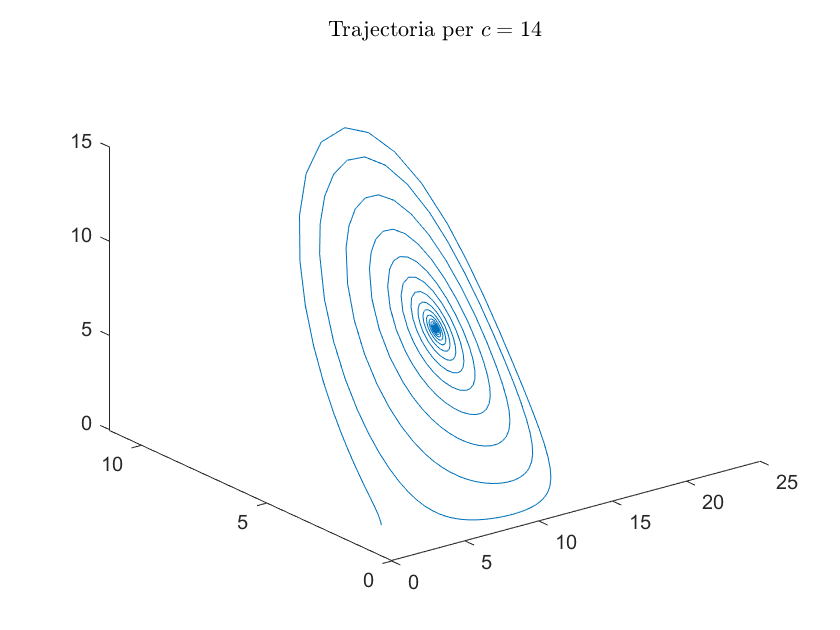


figure(4)
plot3(y(:,1),y(:,2),y(:,3))
title('Trajectoria per $c = 14$','Interpreter', 'latex')

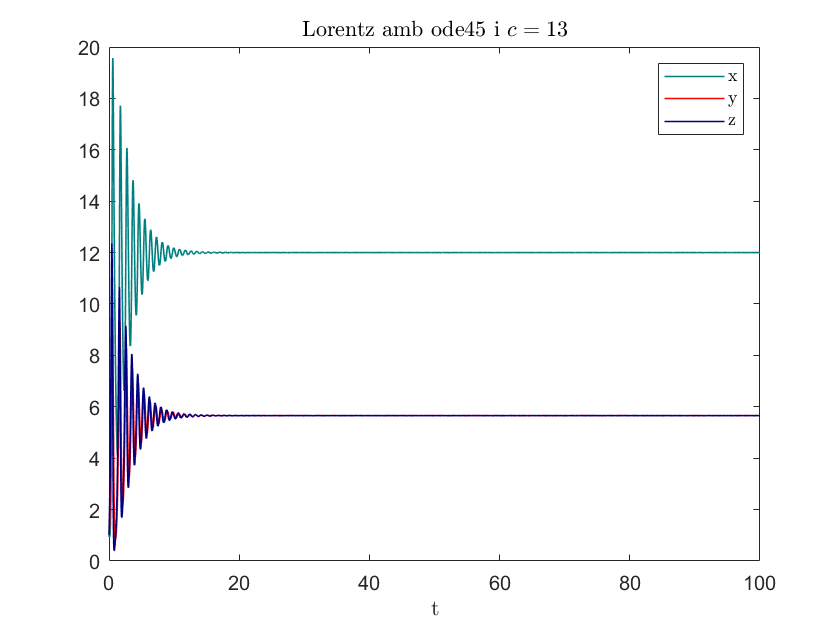



% edos3
[t,y] = ode45(@edos3,[0 100],[1; 1; 1]);
 
figure(5)
plot(t, y(:,1),'Color',[0 0.5 0.5], 'LineWidth',0.8)
hold on
plot(t, y(:,2),'Color',[1 0 0], 'LineWidth',0.8)
plot(t, y(:,3),'Color',[0 0 0.5], 'LineWidth',0.8)
legend('x','y','z','Interpreter', 'latex')
title('Lorentz amb ode45 i $c = 13$','Interpreter', 'latex')
xlabel('t', 'Interpreter',"latex")
hold off

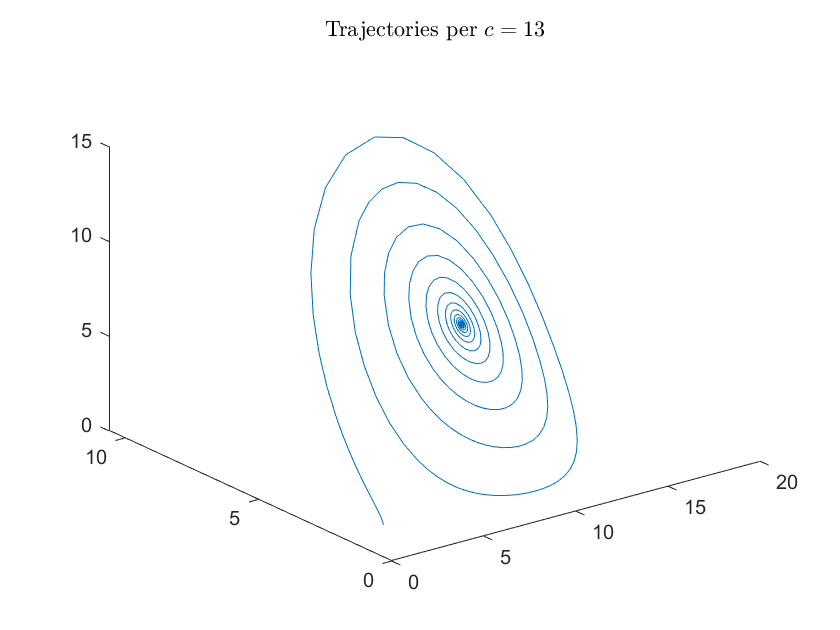


figure(6)
plot3(y(:,1),y(:,2),y(:,3))
title('Trajectories per $c = 13$','Interpreter', 'latex')

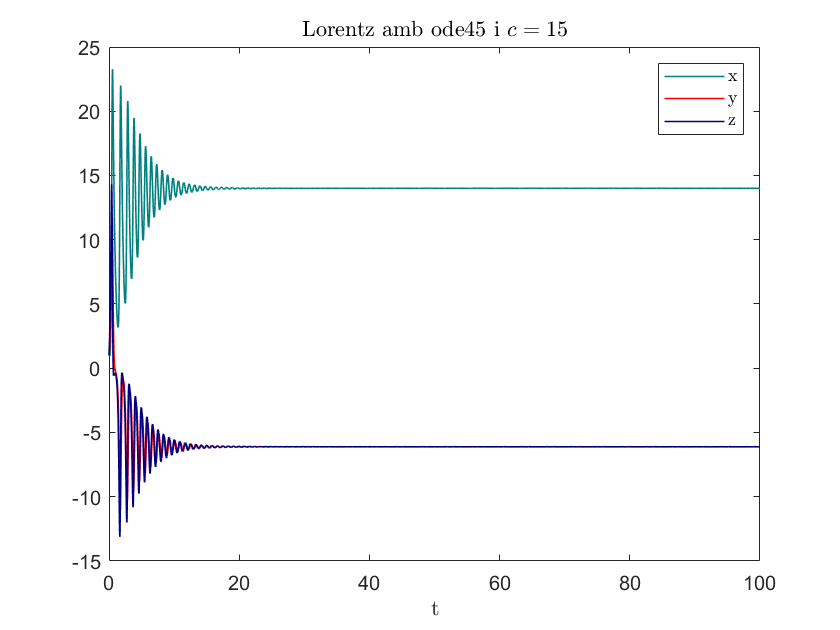




% edos4
[t,y] = ode45(@edos4,[0 100],[1; 1; 1]);
 
figure(5)
plot(t, y(:,1),'Color',[0 0.5 0.5], 'LineWidth',0.8)
hold on
plot(t, y(:,2),'Color',[1 0 0], 'LineWidth',0.8)
plot(t, y(:,3),'Color',[0 0 0.5], 'LineWidth',0.8)
legend('x','y','z','Interpreter', 'latex')
title('Lorentz amb ode45 i $c = 15$','Interpreter', 'latex')
xlabel('t', 'Interpreter',"latex")
hold off

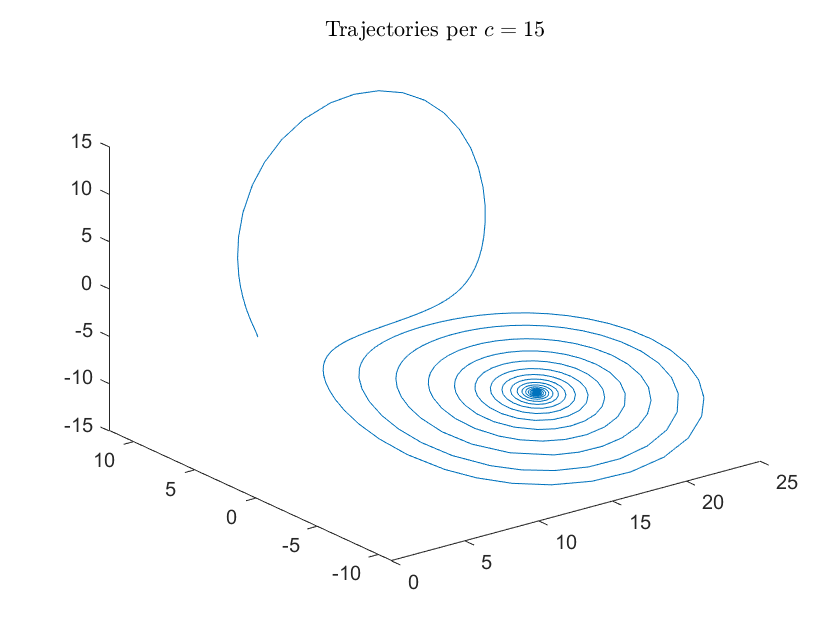


figure(6)
plot3(y(:,1),y(:,2),y(:,3))
title('Trajectories per $c = 15$','Interpreter', 'latex')

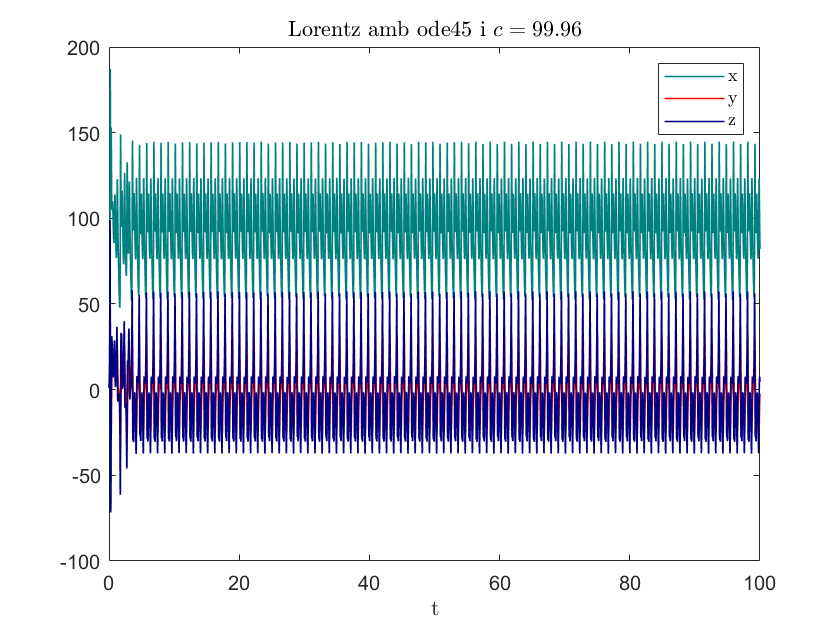



% edos5
[t,y] = ode45(@edos5,[0 100],[1; 1; 1]);
 
figure(5)
plot(t, y(:,1),'Color',[0 0.5 0.5], 'LineWidth',0.8)
hold on
plot(t, y(:,2),'Color',[1 0 0], 'LineWidth',0.8)
plot(t, y(:,3),'Color',[0 0 0.5], 'LineWidth',0.8)
legend('x','y','z','Interpreter', 'latex')
title('Lorentz amb ode45 i $c = 99.96$','Interpreter', 'latex')
xlabel('t', 'Interpreter',"latex")
hold off

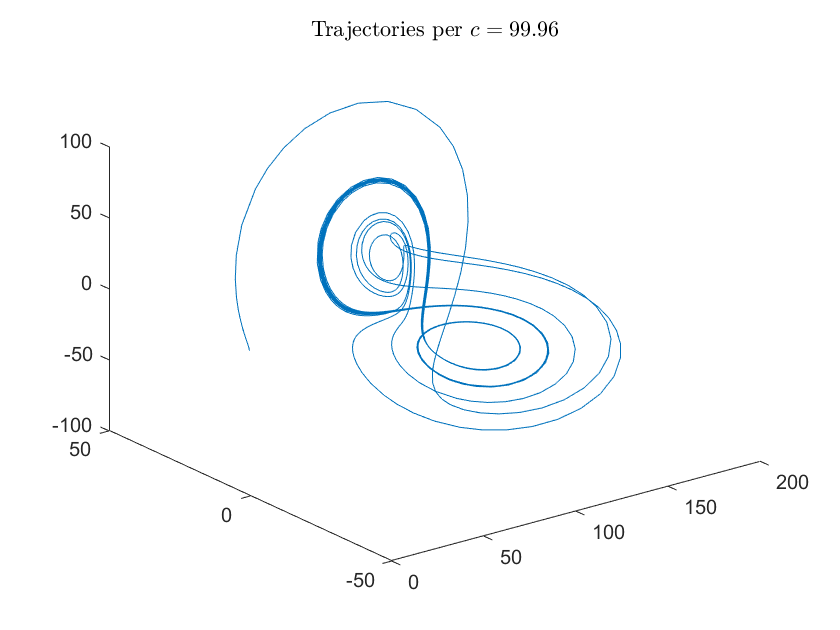


figure(6)
plot3(y(:,1),y(:,2),y(:,3))
title('Trajectories per $c = 99.96$','Interpreter', 'latex')

function F = edos1(t,y)
%   
    a = -8/3; b=-10; c=28;
    F = [a*y(1)+y(2)*y(3); b*(y(2)-y(3)); -y(1)*y(2)+c*y(2)-y(3)];
end
%%%
function F = edos2(t,y)
%   
    % a = -8/3; b=-10; c=28;
    a = -8/3; b=-10; c=14;
    F = [a*y(1)+y(2)*y(3); b*(y(2)-y(3)); -y(1)*y(2)+c*y(2)-y(3)];
end
%%%
function F = edos3(t,y)
%   
    % a = -8/3; b=-10; c=28;
    a = -8/3; b=-10; c=13;
    F = [a*y(1)+y(2)*y(3); b*(y(2)-y(3)); -y(1)*y(2)+c*y(2)-y(3)];
end
%%%
function F = edos4(t,y)
%   
    % a = -8/3; b=-10; c=28;
    a = -8/3; b=-10; c=15;
    F = [a*y(1)+y(2)*y(3); b*(y(2)-y(3)); -y(1)*y(2)+c*y(2)-y(3)];
end
%%%
function F = edos5(t,y)
%   
    % a = -8/3; b=-10; c=28;
    a = -8/3; b=-10; c=99.96;
    F = [a*y(1)+y(2)*y(3); b*(y(2)-y(3)); -y(1)*y(2)+c*y(2)-y(3)];
end
%%%